format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

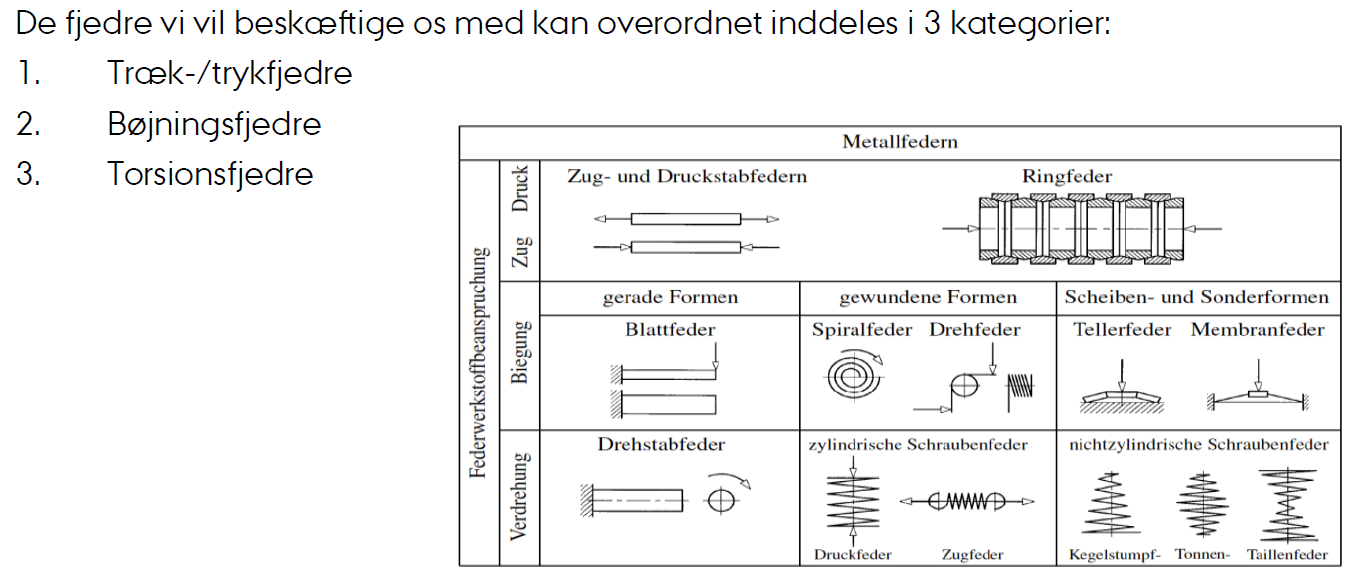

Hookes lov


$$F = -x\cdot k$$


# CYLINDRISKE SKRUEFJEDRE NOMENKLATUR

$D$ - middel diameter [mm]

$D_0$, $D_e$ - Udvendigt diameter [mm]

$D_i$ - Indvendig diameter [mm]

$n_s$ - Sikkerhedsfaktor ved sammenpresset fjeder (normalt $n_s \geq$1,2) **ligning 10-21** - slide 3 side 6

$\xi$ - Sikkerhed mod overløb (typisk 0,15) **ligning 10-20** - slide 3 side 4

$\tau_s$ - Torsionsspænding ved bloktilstand [MPa]

$C$ - Vindingsforholdet ($C = \frac{D}{d}$         $4\le C \le 12$ **ligning 10-18**)

$N_a$ - Antal aktive vindinger ($3 \le N_a \le 15$ **ligning 10-19**)

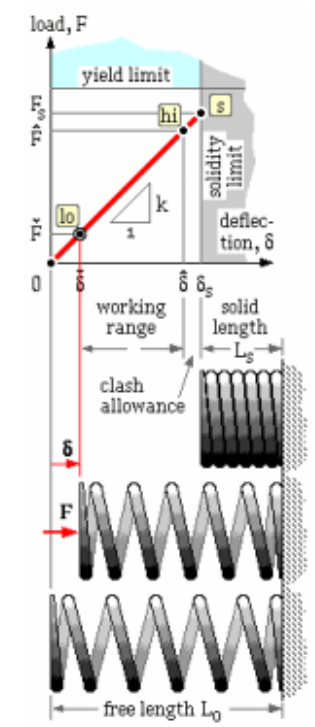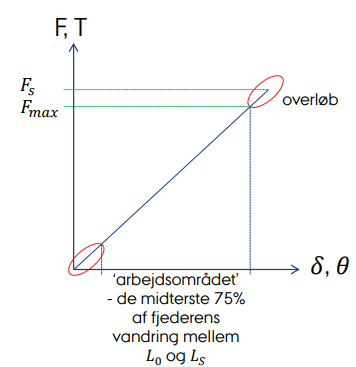

Set removal eller presetting bruges under fremstillingen. Fjederen fremstilles længere end nødvendigt og derefter presses den sammen til **blok længden** for at deformationshærde fjederen. Frilængden reduceres typisk 10-30% i processen. Det anbefales generelt ikke at anvende set removal til dynamisk belastede fjedre!

xi = 1/7; % Sikkerhed mod overløb (typisk 0,15)
n_s = 1.2; 

F_s = 10 * u.N; % Kraft ved blocktilstand F = F_s - F hvor F =0
F_max = 7/8 * F_s;

F_s = (1 + xi) * F_max % ligning(10-17)
% F_s = (1 + xi) * 7/8 * F_s;


### Find et bud på middel diameteren af fjederen

% D_e = D_0;
D_e = 10 * u.mm; %ydre diamerter af fjeder eller diameter af hul
D_i = 10 * u.mm; %indre diamerter af fjeder eller diameter af stang

k_1 = 0.18;
k_2 = 2 * (k_1 * sqrt(F * D_e, 3))^2 / (3 * D_i); % et forsigtitgt bud på fjeder diameteren

%For D_e(ydre diameter) fjeder i hul
d = k_1 * sqrt(F * D_e,3)

%For D_i(indre diameter) fjeder med stang i
d = k_1 * sqrt(F * D_i,3) + k_2

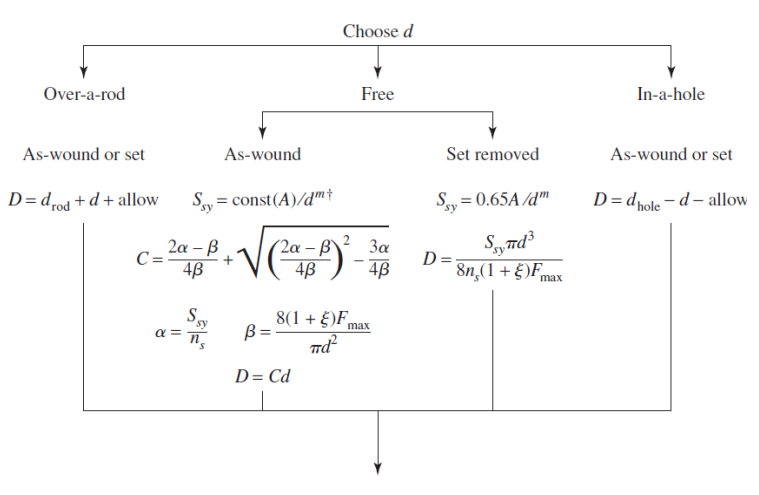

### FOM - – FIGURE OF MERIT (SAMMENLIGNING AF PRIS)

rcm = 1; %relative cost of material tabel 10-4
% fom = rcm * (gamma * pi^2 *d^2 * N_t * D) /4 

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets
instead of parentheses.